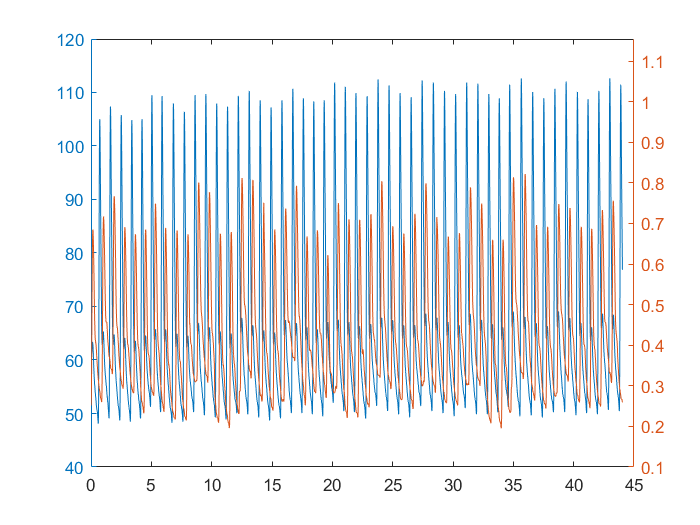

clearvars

addpath('./FreqFeatures')
data = importdata("../physionet.org/segmented_data/3000714_0004-0060.txt");

figure;
yyaxis left
plot(data(:,1), data(:,2))
hold on;
yyaxis right
plot(data(:,1), data(:,3))
hold off

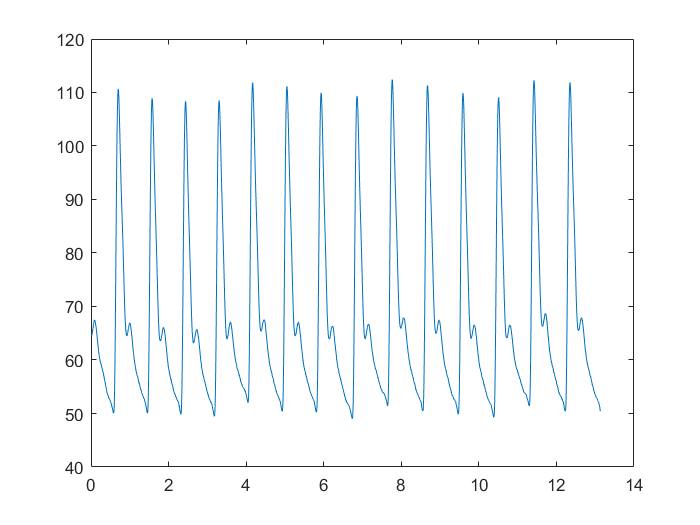

rng = 2001:5000;
time = data(rng,1);
ppg = data(rng,3);
abp = data(rng,2);

segmented = segmentSignal(data(rng,:), 15, 2);

cycle = segmented{1};

cycle(:,1) = cycle(:,1) - cycle(1,1);
figure;
plot(cycle(:,1), cycle(:,2))

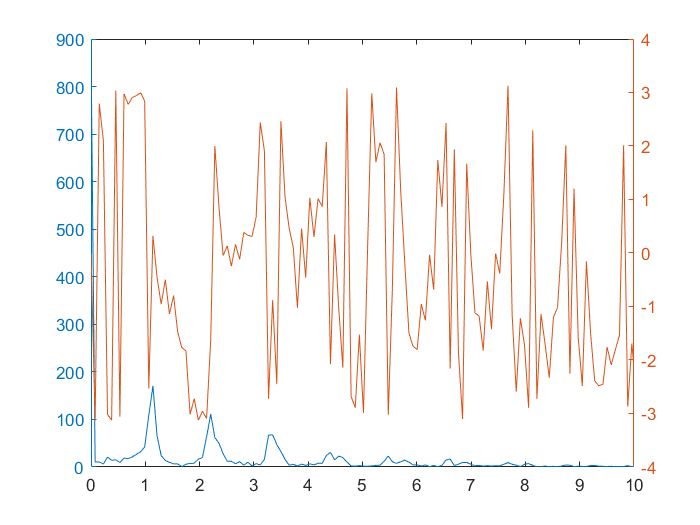


[f, fftABP] = singlesidedFFT(cycle(:,1), cycle(:,2));

figure;
yyaxis left
plot(f, abs(fftABP))
xlim([0 10])
hold on
yyaxis right
plot(f, angle(fftABP))
hold off